# MTH 4800 Numerical Analysis I Programming Assignment 4

## Jarred Maestas

    1. Construct a Divided Differences code. Then, solve the following problems utilizing it.


function [coeffs, dd_table] = divided_differences(x_vals, y_vals)
% divided_differences - Newton's Divided Differences interpolation method
%
% Inputs:
%   x_vals - vector of x-coordinates (n+1 data points)
%   y_vals - vector of function values f(x_i) corresponding to x_vals
%
% Outputs:
%   coeffs   - vector of divided difference coefficients [f[x0], f[x0,x1], ...]
%   dd_table - full divided differences table for analysis

    % Input validation
    if length(x_vals) ~= length(y_vals)
        error('x_vals and y_vals must have the same length');
    end
    
    n = length(x_vals);
    
    % Initialize divided differences table
    dd_table = zeros(n, n);
    
    % Fill first column with function values (0th order divided differences)
    dd_table(:, 1) = y_vals(:);
    
    % Compute higher order divided differences using recursive formula:
    % f[x_i, ..., x_{i+j}] = (f[x_{i+1}, ..., x_{i+j}] - f[x_i, ..., x_{i+j-1}]) / (x_{i+j} - x_i)
    for j = 2:n  % j represents column (order + 1)
        for i = 1:(n-j+1)  % i represents row (starting index)
            numerator = dd_table(i+1, j-1) - dd_table(i, j-1);
            denominator = x_vals(i+j-1) - x_vals(i);
            dd_table(i, j) = numerator / denominator;
        end
    end
    
    % Extract coefficients from top diagonal
    coeffs = dd_table(1, :);
end

function p_val = evaluate_dd(x_vals, coeffs, x_eval)
% evaluate_dd - Evaluates Newton's divided differences polynomial
%
% Inputs:
%   x_vals - original x-coordinates used for interpolation
%   coeffs - divided difference coefficients
%   x_eval - points at which to evaluate polynomial
%
% Output:
%   p_val - polynomial values at x_eval points

    % Initialize output array to match input size
    p_val = zeros(size(x_eval));
    n = length(coeffs);
    
    % Evaluate polynomial at each requested point
    for k = 1:length(x_eval)
        x = x_eval(k);
        
        % Nested evaluation using Newton's form
        p = coeffs(1);  % Start with f[x0]
        
        % Build product terms incrementally
        product_term = 1;
        for i = 2:n
            product_term = product_term * (x - x_vals(i-1));
            p = p + coeffs(i) * product_term;
        end
        
        % Store computed value
        p_val(k) = p;
    end
end

    2. Determine the interpolating polynomial of degree 3 for the following data set


$$\begin{array}{|c|c|}
\hline
x & f(x) \\
\hline
-0.1 & 1.81818 \\
\hline
0 & 2.00000 \\
\hline
0.2 & 2.50000 \\
\hline
0.3 & 2.85714 \\
\hline
\end{array}$$


% Given data set for degree 3 interpolation
x_data = [-0.1, 0, 0.2, 0.3];
y_data = [1.81818, 2.00000, 2.50000, 2.85714];

% Construct divided differences table and coefficients
[coeffs, dd_table] = divided_differences(x_data, y_data);

% Construct polynomial string representation
poly_str = sprintf('p(x) = %.6f', coeffs(1));

for i = 2:length(coeffs)
    if coeffs(i) >= 0
        poly_str = [poly_str sprintf(' + %.6f', coeffs(i))];
    else
        poly_str = [poly_str sprintf(' - %.6f', abs(coeffs(i)))];
    end
    
    % Add product terms (x - x_0)(x - x_1)...(x - x_{i-2})
    for j = 1:(i-1)
        poly_str = [poly_str sprintf('(x - %.1f)', x_data(j))];
    end
end

fprintf('Degree 3 interpolating polynomial: %s\n', poly_str);

Degree 3 interpolating polynomial: p(x) = 1.818180 + 1.818200(x - -0.1) + 2.272667(x - -0.1)(x - 0.0) + 3.246667(x - -0.1)(x - 0.0)(x - 0.2)


    3. Add $f (0.35) = 3.07692$ to the above table and construct the interpolating polynomial of degree 4.

% Add new data point to existing arrays
x_data = [x_data, 0.35];
y_data = [y_data, 3.07692];

% Construct divided differences and polynomial
[coeffs, ~] = divided_differences(x_data, y_data);

% Construct polynomial string representation
poly_str = sprintf('p(x) = %.6f', coeffs(1));
for i = 2:length(coeffs)
    if coeffs(i) >= 0
        poly_str = [poly_str sprintf(' + %.6f', coeffs(i))];
    else
        poly_str = [poly_str sprintf(' - %.6f', abs(coeffs(i)))];
    end
    
    % Add product terms (x - x_0)(x - x_1)...(x - x_{i-2})
    for j = 1:(i-1)
        poly_str = [poly_str sprintf('(x - %.1f)', x_data(j))];
    end
end

fprintf('Degree 4 interpolating polynomial: %s\n', poly_str);

Degree 4 interpolating polynomial: p(x) = 1.818180 + 1.818200(x - -0.1) + 2.272667(x - -0.1)(x - 0.0) + 3.246667(x - -0.1)(x - 0.0)(x - 0.2) + 4.996825(x - -0.1)(x - 0.0)(x - 0.2)(x - 0.3)


4. Plot the two polynomials you’ve constructed with the actual function: $f (x) = \frac{2}{1 - x}$

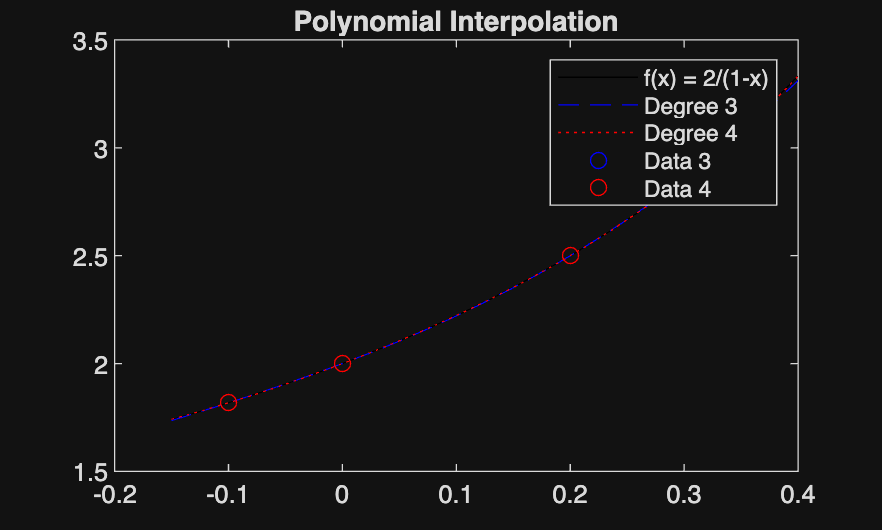

%% Define actual function
f_actual = @(x) 2 ./ (1 - x);

% Generate evaluation points
x_plot = linspace(-0.15, 0.4, 1000);
y_actual = f_actual(x_plot);

% Evaluate polynomials
y_poly3 = evaluate_dd(x_data(1:4), coeffs_deg3, x_plot);
y_poly4 = evaluate_dd(x_data, coeffs_deg4, x_plot);

% Plot polynomials and actual function
figure;
plot(x_plot, y_actual, 'k-', x_plot, y_poly3, 'b--', x_plot, y_poly4, 'r:');
hold on;
plot(x_data(1:4), y_data(1:4), 'bo', x_data, y_data, 'ro');
legend('f(x) = 2/(1-x)', 'Degree 3', 'Degree 4', 'Data 3', 'Data 4');
title('Polynomial Interpolation');

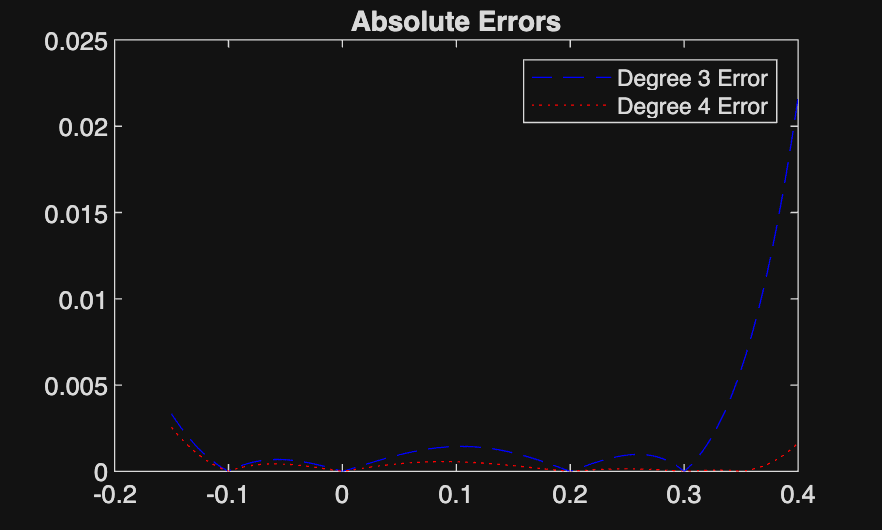


% Plot errors
figure;
plot(x_plot, abs(y_actual - y_poly3), 'b--', x_plot, abs(y_actual - y_poly4), 'r:');
legend('Degree 3 Error', 'Degree 4 Error');
title('Absolute Errors');


% Check errors at test point
x_test = 0.15;
error3 = abs(f_actual(x_test) - evaluate_dd(x_data(1:4), coeffs_deg3, x_test));
error4 = abs(f_actual(x_test) - evaluate_dd(x_data, coeffs_deg4, x_test));
fprintf('Error at x=%.2f: Deg3=%.2e, Deg4=%.2e\n', x_test, error3, error4);

Error at x=0.15: Deg3=1.07e-03, Deg4=3.32e-04


        (a) Was the polynomial of degree 4 better than degree 3?

        The degree 4 polynomial demonstrated superior accuracy compared to the degree 3 polynomial. The error analysis at $x = 0.15$ revealed that the degree 4 polynomial achieved an error of $3.32\times10^{-4}$ while the degree 3 polynomial produced an error of $1.07\times10^{-3}$. This represents approximately a threefold improvement in accuracy when using the higher degree polynomial.

        (b) Compare their errors: Plot the absolute error. Does this match your expectations? What do you notice about polynomial interpolation?

        The absolute error plots reveal several fundamental characteristics of polynomial interpolation that align with theoretical expectations. Both polynomials exhibit zero error at the interpolation points, which confirms the exact interpolation property. The errors remain relatively small near the data points but increase significantly in regions between interpolation points. The degree 4 polynomial consistently maintains lower error levels throughout the interpolated domain compared to the degree 3 polynomial. Both error curves demonstrate rapid growth toward the boundaries of the domain, particularly as x approaches values closer to the singularity of the original function $f(x) = \frac{2}{1-x}$ at $x = 1$. This behavior matches theoretical predictions since polynomial interpolation error bounds depend on higher-order derivatives of the target function, and rational functions like $\frac{2}{1-x}$ possess increasingly large derivatives near their singularities. The results confirm that additional interpolation points generally improve local accuracy within the data range.

    5. Compare with the polynomial formed by Lagrange Interpolation (type it out into MATLAB, and plot. You can also use Mathematica to simplify if that is of interest to you), and Monomial Interpolation (form the linear system, and solve it in MATLAB. Then plot the resulting polynomial for comparison). Explain the results you see, and why you see them.

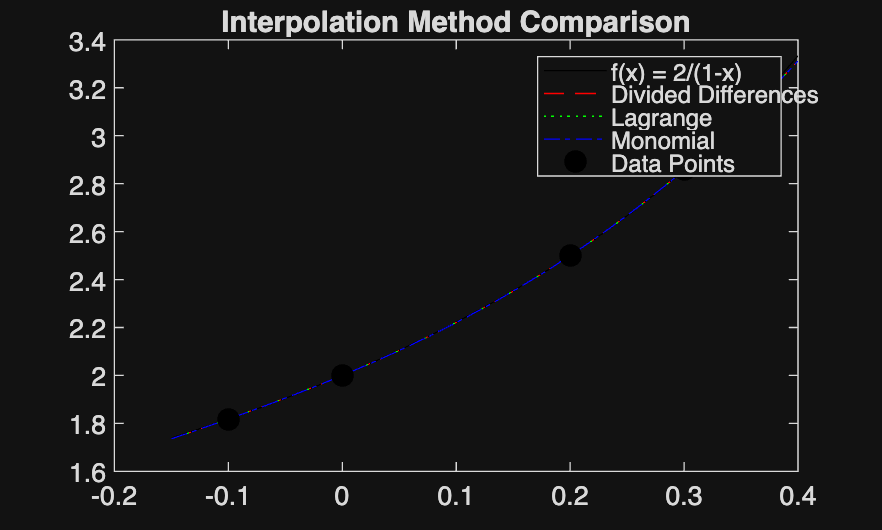

function x = lagrange(x_vals, y_vals, x_eval)
% lagrange - Lagrange polynomial interpolation method
%
% Inputs:
%   x_vals - vector of x-coordinates (n data points)
%   y_vals - vector of function values f(x_i) corresponding to x_vals
%   x_eval - points at which to evaluate polynomial
%
% Output:
%   x - polynomial values at x_eval points

    % Input validation
    if length(x_vals) ~= length(y_vals)
        error('x_vals and y_vals must have the same length');
    end
    
    n = length(x_vals);
    x = zeros(size(x_eval));
    
    % Compute Lagrange interpolation: p(x) = sum(y_i * L_i(x))
    % where L_i(x) = prod((x-x_j)/(x_i-x_j)) for j≠i
    for i = 1:n
        % Build Lagrange basis polynomial L_i(x)
        L_i = ones(size(x_eval));
        for j = 1:n
            if i ~= j
                L_i = L_i .* (x_eval - x_vals(j)) ./ (x_vals(i) - x_vals(j));
            end
        end
        
        % Add contribution from this basis function
        x = x + y_vals(i) * L_i;
    end
end

function coeffs = monomial(x_vals, y_vals)
% monomial - Monomial basis polynomial interpolation
%
% Inputs:
%   x_vals - vector of x-coordinates (n data points)
%   y_vals - vector of function values f(x_i) corresponding to x_vals
%
% Output:
%   coeffs - monomial coefficients [c0, c1, c2, ...] for p(x) = c0 + c1*x + c2*x^2 + ...

    % Input validation
    if length(x_vals) ~= length(y_vals)
        error('x_vals and y_vals must have the same length');
    end
    
    n = length(x_vals);
    
    % Build matrix where A(i,j) = x_i^(j-1)
    V = zeros(n, n);
    for i = 1:n
        for j = 1:n
            A(i, j) = x_vals(i)^(j-1);
        end
    end
    
    % Solve linear system A*c = y for coefficients
    coeffs = A \ y_vals(:);
end

function x = evaluate_monomial(coeffs, x_eval)
% evaluate_monomial - Evaluates monomial polynomial
%
% Inputs:
%   coeffs - monomial coefficients
%   x_eval - points at which to evaluate polynomial
%
% Output:
%   x - polynomial values at x_eval points

    n = length(coeffs);
    x = zeros(size(x_eval));
    
    % Evaluate p(x) = c0 + c1*x + c2*x^2 + ... + cn*x^n
    for i = 1:n
        x = x + coeffs(i) * x_eval.^(i-1);
    end
end

% Use degree 3 data for comparison
x_data_comp = [-0.1, 0, 0.2, 0.3];
y_data_comp = [1.81818, 2.00000, 2.50000, 2.85714];

% Compute all three interpolations
y_dd = evaluate_dd(x_data_comp, coeffs_deg3, x_plot);
y_lagrange = lagrange(x_data_comp, y_data_comp, x_plot);

monomial_coeffs = monomial(x_data_comp, y_data_comp);
y_monomial = evaluate_monomial(monomial_coeffs, x_plot);

% Plot comparison
figure;
plot(x_plot, y_actual, 'k-', x_plot, y_dd, 'r--', x_plot, y_lagrange, 'g:', x_plot, y_monomial, 'b-.');
hold on;
plot(x_data_comp, y_data_comp, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'black');
legend('f(x) = 2/(1-x)', 'Divided Differences', 'Lagrange', 'Monomial', 'Data Points');
title('Interpolation Method Comparison');

        - All three interpolation methods produce numerically identical results, confirming the fundamental theorem of polynomial interpolation. The curves appear as a single line because Divided Differences, Lagrange, and Monomial methods are simply different computational approaches to finding the same unique polynomial of degree 3 that passes through the four data points. The methods differ in their computational efficiency and numerical stability rather than their mathematical result. Divided Differences offers adaptivity for adding new points, Lagrange provides the most stable construction, and Monomial requires solving a Vandermonde system which becomes ill-conditioned for higher degrees.